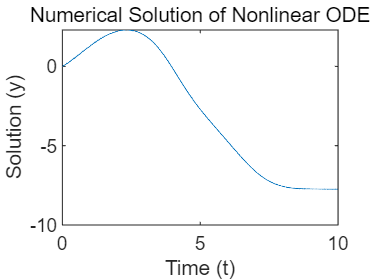


% 设置时间区间和初始条件
tspan = 0:0.01:10; % 时间从0到10
y0 = [0; 1]; % 初始条件 y(0) = 0, dy/dt(0) = 1

% 使用ode45求解非线性微分方程组
[t, y] = ode45(@nonlinearODE, tspan, y0);

% 绘制结果
plot(t, y(:,1));
xlabel('Time (t)');
ylabel('Solution (y)');
title('Numerical Solution of Nonlinear ODE');


% 定义非线性微分方程组

function dydt = nonlinearODE(t, y)
    dydt = zeros(2,1);
    dydt(1) = y(2);
    dydt(2) = -sin(y(1)) + cos(t);
end